**Preliminaries**

clear
clc 
ct.A=[-3.7 -7.5; 0 1];ct.B=[0;1];%System matrices
ct.nx=length(ct.A);ct.nu=size(ct.B,2);
if rank(ctrb(ct.A,ct.B))==length(ct.A)%Check controllability
    disp('CT System Controllable')
end

CT System Controllable


[ct.V,ct.D]=eig(ct.A);

%Closed Loop
ct.clpoles=[-1+2i,-1-2i];%Desired closed loop poles
ct.K=place(ct.A,ct.B,ct.clpoles);%Static Feedback Gain

addpath(genpath("C:\Users\amato\OneDrive\Documenten\TU\MSC S&C\Year 1\Q3 23-24\MPC"))

**Question 1**

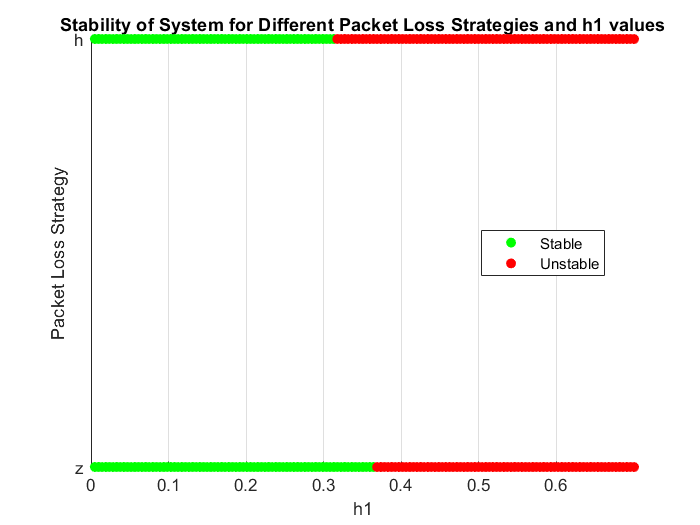

q1.h1min = 0.005;q1.h1max = 0.7;%range of h1
numPoints = 150;q1.h1range=linspace(q1.h1min,q1.h1max,numPoints);
plstrategy=['z','h'];%packet loss strategy
q1.sys1stab=zeros(length(q1.h1range),length(plstrategy));

for s=1:length(plstrategy)
    for i=1:length(q1.sys1stab)
        h1 = q1.h1range(i);
        [F1,F0]=cttodt_pl(ct.A,ct.B,h1,plstrategy(s),ct.K); 
        nx=size(F1,1);
        P=sdpvar(nx,nx);Q=1e-3*eye(nx,nx);
        cons=[P>=1e-3*eye(nx),...
              (F0^3)'*P*(F0^3)-P<=-Q,...
              (F0^2*F1)'*P*(F0^2*F1)-P<=-Q];
        obj=0;ops=sdpsettings('verbose',0,'solver','sdpt3');
        sol=optimize(cons,obj,ops);%Solve
         if sol.problem==0
             q1.sys1stab(i,s)=1;%1 means stable
         else
             q1.sys1tab(i,s)=0;%0 means unstable
         end
        clear P
    end
end


% Plotting the results
figure;
hold on;
for s = 1:length(plstrategy)
    % Get stable and unstable points
    stable_points = q1.h1range(q1.sys1stab(:, s) == 1);
    unstable_points = q1.h1range(q1.sys1stab(:, s) == 0);
    
    % Plot stable points
    scatter(stable_points, s * ones(size(stable_points)), 'g', 'filled');
    % Plot unstable points
    scatter(unstable_points, s * ones(size(unstable_points)), 'r', 'filled');
end

% Customize the plot
legend({'Stable', 'Unstable'}, 'Location', 'best');
xlabel('h1');
ylabel('Packet Loss Strategy');
yticks(1:length(plstrategy));
yticklabels({'z', 'h'});
title('Stability of System for Different Packet Loss Strategies and h1 values');
grid on;
hold off;

**Question 3**

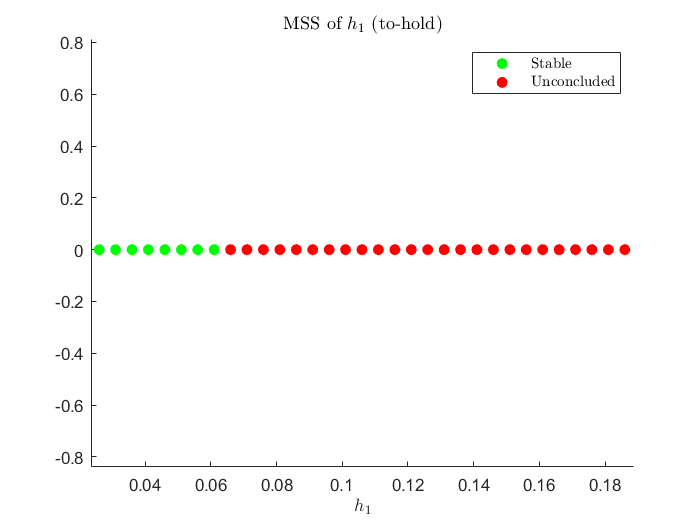

% Define the probabilities
p1 = 0.99;p2 = 0.49;p3 = 0.02;

% Create the matrix T
T = [0   0   p1  0   0   0   1-p1;
     0   0   p1  0   0   0   1-p1;
     0   0   0   p2  p2  p3  0;
     p1 1-p1 0   0   0   0   0;
     p1 1-p1 0   0   0   0   0;
     p1 1-p1 0   0   0   0   0;
     0   0   0   p2  p2  p3  0];

%Define the CT system matrices of Sys2
ct.A2=(1/3)*ct.A;ct.B2=ct.B;
ct.K2=place(ct.A2,ct.B2,ct.clpoles);%Static Feedback Gain

%Range of h1
h_values = 0.001:0.005:0.2;
%Store Results
stable_points = [];
unstable_points = [];

for h1 = h_values
    %Sys Matrices (1,3) and (2,7) are equal
    Acl1 = mjls(h1, ct.K, ct.K2, 1);Acl2 = mjls(h1, ct.K, ct.K2, 2);
    Acl4 = mjls(h1, ct.K, ct.K2, 4);Acl5 = mjls(h1, ct.K, ct.K2, 5);
    Acl6 = mjls(h1, ct.K, ct.K2, 6);
    Acl3 = Acl1; Acl7 = Acl2;
    
    nx = length(Acl1);eps = 1e-3; % machine precision
    S = eye(length(T)); % Selection Matrix
    
    %Opti Variables
    P1 = sdpvar(nx, nx); P2 = sdpvar(nx, nx);
    P3 = sdpvar(nx, nx); P4 = sdpvar(nx, nx);
    P5 = sdpvar(nx, nx); P6 = sdpvar(nx, nx);
    P7 = sdpvar(nx, nx);

    %LMIs
    cons = [P1 - ((T(1,:) * S(:,3)) * (Acl3' * P3 * Acl3) ...
           + T(1,:) * S(:,7) * (Acl7' * P7 * Acl7)) >= eps * eye(nx), ...
           
          P2 - ((T(2,:) * S(:,3)) * (Acl3' * P3 * Acl3) ...
          + T(2,:) * S(:,7) * (Acl7' * P7 * Acl7)) >= eps * eye(nx), ...
          
          P3 - ((T(3,:) * S(:,4)) * (Acl4' * P4 * Acl4) ...
          + T(3,:) * S(:,5) * (Acl5' * P5 * Acl5) ...
          + T(3,:) * S(:,6) * (Acl6' * P6 * Acl6)) >= eps * eye(nx), ...
          
          P4 - ((T(4,:) * S(:,1)) * (Acl1' * P1 * Acl1) ...
          + T(3,:) * S(:,2) * (Acl2' * P2 * Acl2)) >= eps * eye(nx), ...
          
          P5 - ((T(5,:) * S(:,1)) * (Acl1' * P1 * Acl1) ...
          + T(5,:) * S(:,2) * (Acl2' * P2 * Acl2)) >= eps * eye(nx), ...
          
          P6 - ((T(6,:) * S(:,1)) * (Acl1' * P1 * Acl1) ...
          + T(6,:) * S(:,2) * (Acl2' * P2 * Acl2)) >= eps * eye(nx), ...
          
          P7 - ((T(7,:) * S(:,4)) * (Acl4' * P4 * Acl4) ...
          + T(7,:) * S(:,5) * (Acl5' * P5 * Acl5) ...
          + T(7,:) * S(:,6) * (Acl6' * P6 * Acl6)) >= eps * eye(nx), ...
          
          P1 >= eps * eye(nx), P2 >= eps * eye(nx), P3 >= eps * eye(nx), ...
          P4 >= eps * eye(nx), P5 >= eps * eye(nx), P6 >= eps * eye(nx), ...
          P7 >= eps * eye(nx)];

    %Optimize
    obj = 0; 
    ops = sdpsettings('verbose', 0, 'solver', 'sdpt3', 'debug', 1);
    sol = optimize(cons, obj, ops); % Solve
    
    %Save sampling time as Stable or Unstable
    if sol.problem == 0
        stable_points = [stable_points, h1];
    else
        unstable_points = [unstable_points, h1];
    end
end

% Plot the results
figure;
hold on;
plot(stable_points, zeros(size(stable_points)), 'go', 'MarkerFaceColor', 'g');
plot(unstable_points, zeros(size(unstable_points)), 'ro', 'MarkerFaceColor', 'r');
xlabel({'$h_1$'},'interpreter','latex');
title({'MSS of $h_1$ (to-hold)'},'interpreter','latex');
legend({'Stable', 'Unconcluded'},'Interpreter','latex');
hold off;

**Question 3**

hrange = linspace(0.005,0.15,50);
stable_points = [];
unstable_points = [];

for h = hrange
    taurange = 0:0.005:(h-0.005);
    for tau = taurange
        [Hf, Hg] = H(h,tau,ct.A,ct.V);
        K = [ct.K 0];
        H1 = Hf.mi_mi - Hg.mi_mi * K;
        H2 = Hf.ma_ma - Hg.ma_ma * K;
        H3 = Hf.mi_ma - Hg.mi_ma * K;
        H4 = Hf.ma_mi - Hg.ma_mi * K;
        nx = length(H1);
        
        P = sdpvar(nx, nx);
        % gam = sdpvar(1);
        gam=1e-5;
        cons = [P >= 1e-3 * eye(nx, nx), ...
                H1' * P * H1 - (1-gam)*P <=0, ...
                H2' * P * H2 - (1-gam)*P <=0, ...
                H3' * P * H3 - (1-gam)*P <=0, ...
                H4' * P * H4 - (1-gam)*P <=0];
        
        obj = 0;
        ops = sdpsettings('verbose', 0,'solver','sdpt3');
        sol = optimize(cons, obj, ops);
        
        if sol.problem == 0 
            stable_points = [stable_points; h, tau];
        else 
            unstable_points = [unstable_points; h, tau];
        end
    end
end


% Plotting
figure;
hold on;

% Plot stable points in green
if ~isempty(stable_points)
    scatter(stable_points(:, 1), stable_points(:, 2), 'g', 'filled');
end

% Plot unstable points in red
if ~isempty(unstable_points)
    scatter(unstable_points(:, 1), unstable_points(:, 2), 'r', 'filled');
end

% Labels and title
xlabel('h');
ylabel('tau');
title('Stability of Points');
legend({'Stable Points', 'Unstable Points'}, 'Location', 'Best');
grid on;
hold off;

%% Refined Approximation
%Obtain big F and big G matrices
[bigF,biG]=Poly()






